# Creazione delle tabelle pivot tramite il task "Pivot Table"

Caricamento dati


miofile="Firm.xlsx"; % Caricamento file Firm.xlsx dentro MATLAB 
X=readtable(miofile,"ReadRowNames",true);


Inserimento del task "Pivot Table"

% Create pivoted table
pivotedData = pivot(X, Rows="Gender", Columns="Education", DataVariable="Wage", ...
    Method="mean", RowLabelPlacement="rownames")

pivotedData = 2×3 table
            A          B          C   
         _______    _______    _______

    F    2169.50    2356.00    2710.19
    M    2061.43    2659.59    2846.88


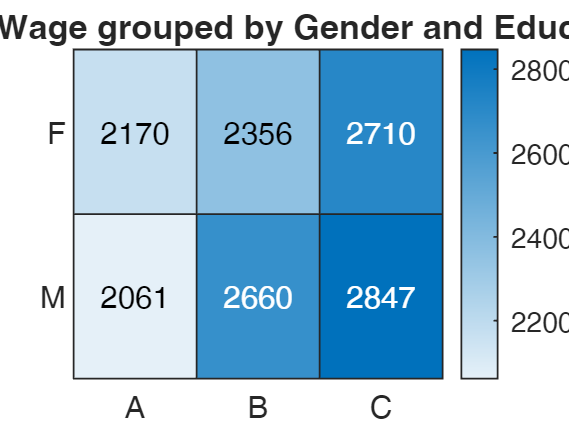


% Generate heatmap chart
rowNames = pivotedData.Properties.RowNames;
colNames = pivotedData.Properties.VariableNames;
data = table2array(pivotedData);
heatmap(colNames,rowNames,data, Interpreter="none", ...
    Title="Mean of Wage grouped by Gender and Education");


clear rowNames colNames data